# Regelkreis mit Verzögerung (PT2)

## Strecke


$$G_0(s) = \frac{100}{s^2 + 10s + 100}$$


% PT2-Verhalten
G0 = tf(1,[0.01 0.1 1]);

## Einstellung PI-Regler


$$u = K \Big[ (w - y) + \frac{1}{T_\text{i}} \int (w-y) \mathrm d t + T_\text{d} \frac{\mathrm d}{\mathrm d t} (w-y) \Big]$$


% Parameter des PI-Reglers
Kp = 10;
Ti = 0.1;
Td = 1;

% PI-Regler
K = Kp*tf([Td*Ti Ti 1],[Ti 0]);

## Offener und Geschlossener Kreis

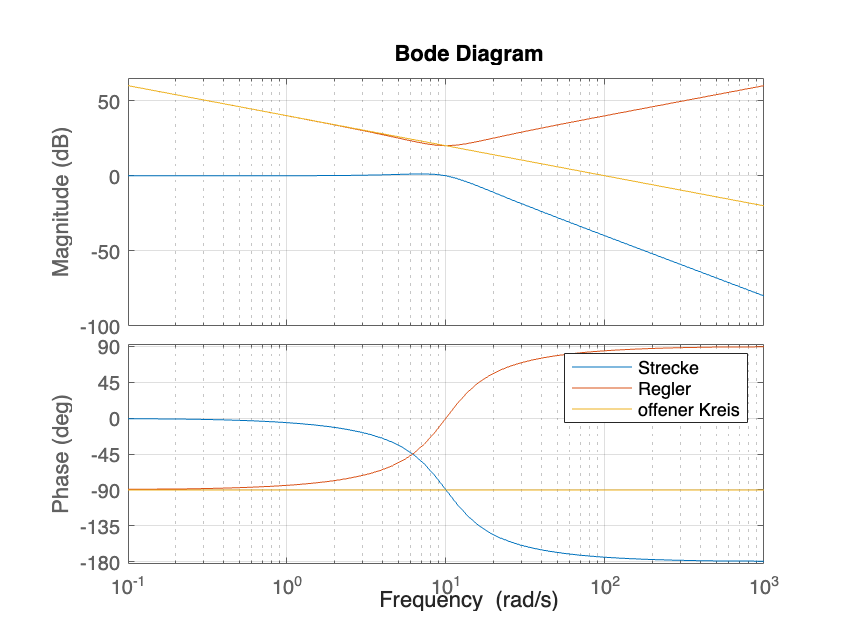

% Offener Kreis
GK0 = K*G0;

% Bode-Diagramme
bode(G0,K,GK0)
grid on
legend('Strecke','Regler','offener Kreis')

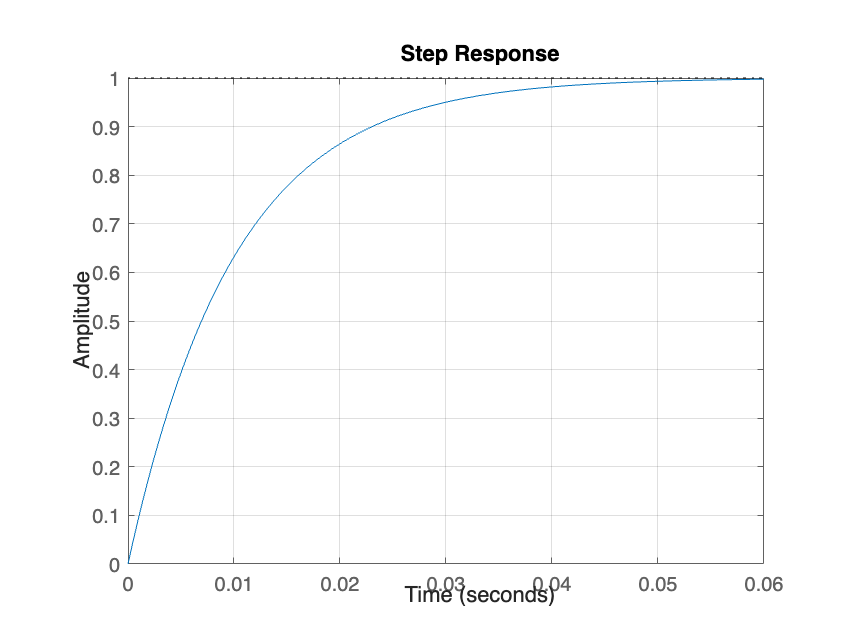


% Geschlossener Kreis
GRK = feedback(GK0,1); %GK0/(1 + GK0);

% Sprungantwort geschlossener Kreis
step(GRK)
grid on